clear
close all
clc

addpath(genpath('C:\Program Files\Mosek\11.0\toolbox\r2019b'));
addpath(genpath('.\YALMIP'));

We consider the example from the paper "Control Contraction Metrics: Convex and Intrinsic Criteria for Nonlinear Feedback Design" scaled down to a 2D system.

nx = 2;
nu = 1;
ny = 2;
f = @(x) ([-x(1,:)+x(2,:).^2; x(1,:).^2-2*x(1,:).*x(2,:)+x(2,:)]);
B = [0;1];
C = eye(nx);
D = zeros(nx,nu);

% nx = 3;
% nu = 1;
% ny = 3;
% f = @(x) ([-x(1)+x(3); x(1)^2-x(2)-2*x(1)*x(3)+x(3); -x(2)]);
% B = [0;0;1];
% C = eye(nx);
% D = zeros(nx,nu);

nlsys.nx = nx;
nlsys.nu = nu;
nlsys.ny = ny;
nlsys.f = f;
nlsys.g = @(x,u) (B*u);
nlsys.h = @(x,u) (C*x + D*u);

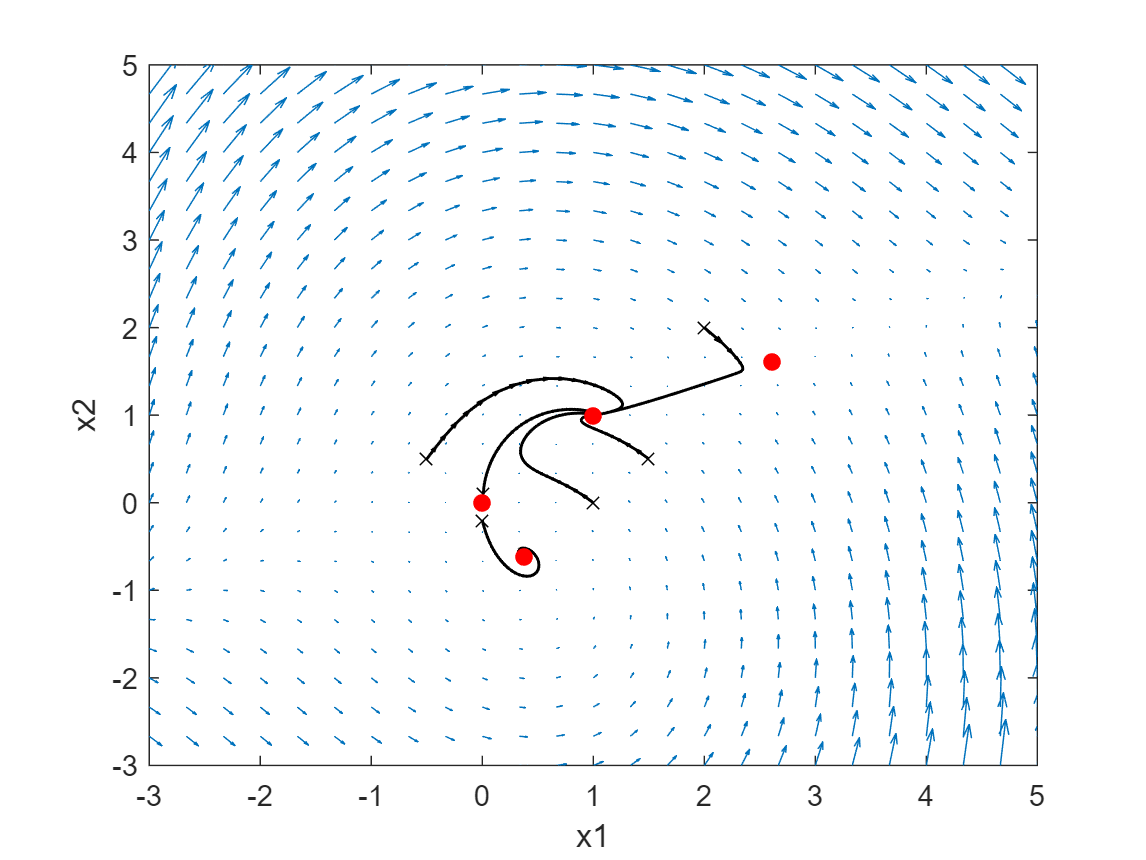

% Find equilibrium points
x_sym = sym('x',[nx,1],'real');
sols = solve(f(x_sym) == 0,x_sym);

% Visualize vector field
xis = linspace(-3,5,2.5e1);
[x1s,x2s] = meshgrid(xis, xis);
f1s = zeros(length(xis),length(xis));
f2s = zeros(length(xis),length(xis));
for i1=1:length(xis)
    for i2=1:length(xis)
        xi = [x1s(i1,i2);x2s(i1,i2)];
        xdi = f(xi);
        f1s(i1,i2) = xdi(1);
        f2s(i1,i2) = xdi(2);
    end
end


figure
% Plot vector field
quiver(x1s,x2s,f1s,f2s,'AutoScale','on','AutoScaleFactor',1.3)
hold on
% Plot trajectories
x0s = [  0, 0.01, -0.5, 1.5, 1, 2;
       -0.2, 0.1,  0.5, 0.5, 0, 2];
Narr = 1;  % adjust arrow spacing
for i=1:size(x0s,2)
    scatter(x0s(1,i),x0s(2,i),'kx')
    [~,traji] = simRK4(f, x0s(:,i), 100, 0.1);
    plot(traji(1,:),traji(2,:),'LineWidth',1)
    x1arr = traji(1,1:Narr:end-1);
    x2arr = traji(2,1:Narr:end-1);
    dx1arr = diff(traji(1,1:Narr:end));
    dx2arr = diff(traji(2,1:Narr:end));
    quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'k', 'filled', ...
           'LineWidth', 1, 'MaxHeadSize', 5);
end
% Plot Equilibrium points
scatter(sols.x1,sols.x2,'ro','filled')
axis tight
xlabel('x1')
ylabel('x2')
xlim([-3,5])
ylim([-3,5])

The system has two equilibrium points: $x^*=(0,0)$, which is unstable, and $x^*=(1,1)$, which is locally asymptotically stable.

We are interest in stabilizing the system at $x^*=(0,0)$.

xeq = zeros(nx,1);

Now we compute the linearized system at the origin

x = sym('x', [nx,1], 'real');
u = sym('u', [nu,1], 'real');
xdot_ = f(x) + B*u

$$xdot\_ = \left(\begin{array}{c} {x_{2}}^{2}-x_{1}\\ {x_{1}}^{2}-2\,x_{2}\,x_{1}+u_{1}+x_{2} \end{array}\right)$$


nablax = jacobian(xdot_, x)

$$nablax = \left(\begin{array}{cc} -1 & 2\,x_{2}\\ 2\,x_{1}-2\,x_{2} & 1-2\,x_{1} \end{array}\right)$$

A_ = subs(nablax, [x;u], [xeq; zeros(nu,1)])

$$A\_ = \left(\begin{array}{cc} -1 & 0\\ 0 & 1 \end{array}\right)$$

A = double(A_);

linSys = ss(A,B,C,D);

We create a local LQR controller to impose as constraint on the differential controller.

Q = eye(nx);
R = eye(nu);
P = are(A,B*inv(R)*B',Q)

P =     0.5000         0
         0    2.4142


Klqr_K = -inv(R)*B'*P

Klqr_K =          0   -2.4142


Klqr = @(x) (-inv(R)*B'*P*x);

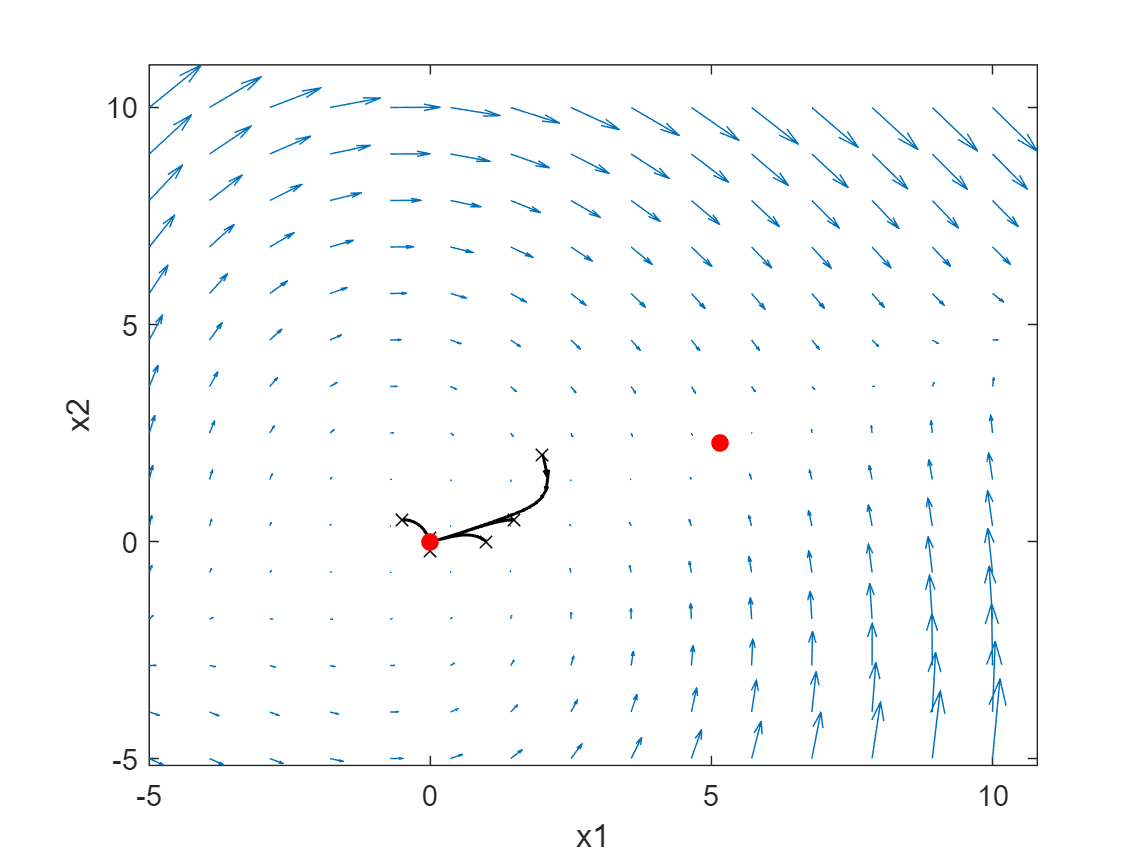

% Find equilibrium points
x_sym = sym('x',[nx,1],'real');
sols = solve(f(x_sym)+B*Klqr_K*x_sym == 0,x_sym);

% Visualize vector field
xis = linspace(-5,10,1.5e1);
[x1s,x2s] = meshgrid(xis, xis);
f1s = zeros(length(xis),length(xis));
f2s = zeros(length(xis),length(xis));
for i1=1:length(xis)
    for i2=1:length(xis)
        xi = [x1s(i1,i2);x2s(i1,i2)];
        xdi = f(xi)+B*Klqr_K*xi;
        f1s(i1,i2) = xdi(1);
        f2s(i1,i2) = xdi(2);
    end
end


figure
% Plot vector field
quiver(x1s,x2s,f1s,f2s,'AutoScale','on','AutoScaleFactor',1.3)
hold on
% Plot trajectories
x0s = [  0, 0.01, -0.5, 1.5, 1, 2;
       -0.2, 0.1,  0.5, 0.5, 0, 2];
Narr = 1;  % adjust arrow spacing
for i=1:size(x0s,2)
    scatter(x0s(1,i),x0s(2,i),'kx')
    [~,traji] = simRK4(@(xi) (f(xi)+B*Klqr_K*xi), x0s(:,i), 100, 0.1);
    plot(traji(1,:),traji(2,:),'LineWidth',1)
    x1arr = traji(1,1:Narr:end-1);
    x2arr = traji(2,1:Narr:end-1);
    dx1arr = diff(traji(1,1:Narr:end));
    dx2arr = diff(traji(2,1:Narr:end));
    quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'k', 'filled', ...
           'LineWidth', 1, 'MaxHeadSize', 5);
end
% Plot Equilibrium points
scatter(sols.x1,sols.x2,'ro','filled')
axis tight
xlabel('x1')
ylabel('x2')

% xlim([-5,10])
% ylim([-5,10])

Now, we can look for a contraction metric $W$ and a nonlinear (polynomial) differential controller gain $Y(x)$.

yalmip('clear')

x = sdpvar(nlsys.nx,1);

f_sos = f(x);

% Monomial basis functions
Z = monolist(x,1);
% Z = [1; x(1); x(2); x(1)*x(2); x(1)^2];
% Z = [1; x(1); x(1)^2];
% Z = [1; x(1)];

% Define Y as nu by nx polynomial matrix
rhoM = sdpvar(length(Z)*1, length(Z)*1);
rho = Z'*rhoM*Z;
% YM = sdpvar(length(Z)*nu, length(Z)*nx);
% Y = kron(eye(nu),Z)'*YM*kron(eye(nx),Z);

% W = sdpvar(nx,nx);
WM = sdpvar(length(Z)*nx, length(Z)*nx);
W = kron(eye(nx), Z)'*WM*kron(eye(nx), Z);

lambda = 1e-2;
nablaf_sos = jacobian(f_sos, x);
dirW = 0;
for i=1:nx
    dirW = dirW + jacobian(W,x(i))*f_sos(i);
end
Vdot = -dirW + nablaf_sos*W + W*nablaf_sos' -rho*B*B' + 2*lambda*W;
% Vdot = -dirW + nablaf_sos*W + W*nablaf_sos' + B*Y + Y'*B' + 2*lambda*W;

% Box constraint
% g = [0.5-x(1);0.5+x(1);0.5-x(2);0.5+x(2)];
% % Positivstellensatz polynomials
% [s1,c1] = polynomial(x,2);
% [s2,c2] = polynomial(x,2);
% [s3,c3] = polynomial(x,2);
% [s4,c4] = polynomial(x,2);
% pssp = [s1;s2;s3;s4];
% pssc = [c1(:);c2(:);c3(:);c4(:)];

% F = [sos( -( Vdot + 1e-6*eye(nx)) -pssp'*g )]; % Vdot < 0
F = [sos( -( Vdot + 1e-6*eye(nx)) )]; % Vdot < 0

% F = [F, W >= 0];
% F = [F, sos(W -pssp'*g)]; % W >= 0
F = [F, sos(W)]; % W >= 0

% Local equivalence with LQR controller
F = [F, replace(rho,x,xeq) == 2*inv(R)];
% F = [F, replace(Y,x,xeq) == -inv(R)*B'];
F = [F, replace(W,x,xeq) == inv(P)];

% M(x) > 1e-4*I => W(x) < 1e4*I => W(x) -1e4*I < 0
% M(x) < 1e4*I => W(x) > 1e-4*I => W(x) -1e-4 > 0
% Mmin = 1e-4; Mmax = 1e5;
% F = [F, sos( -(W - (1/Mmin)*eye(nx)) ), sos( W -(1/Mmax)*eye(nx) )];
% Uniform bounds on W
% Zx = [1; x(:).^12];
Zx = [1];
Ax = sdpvar(length(Zx)*nx, length(Zx)*nx);
boundx = kron(eye(nx),Zx)'*Ax*kron(eye(nx),Zx);
F = [F, sos( -(W -  boundx) ), sos(boundx)];
Ax_ = sdpvar(length(Zx)*nx, length(Zx)*nx);
boundx_ = kron(eye(nx),Zx)'*Ax_*kron(eye(nx),Zx);
F = [F, sos(W -  boundx_), sos(boundx_)];

% F = [F,sos(s1),sos(s2),sos(s3),sos(s4)];

ops = sdpsettings('solver','mosek','verbose',1);
% solvesos(F, norm(coefficients(rho,x),1), ops, [rhoM(:);WM(:);pssc]);
solvesos(F, norm(coefficients(W,Z),1) + norm(Ax(:),1) + norm(coefficients(rho,Z),1), ...
         ops, [rhoM(:);WM(:);Ax(:);Ax_(:)]);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 70 parametric variables and 2 independent variables.
Detected 6 linear inequalities, 2 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Initially 6 monomials in R^2
Newton polytope (1 LPs).........Keeping 3 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 3 monomials in R^2
Newton polytope (0 LPs).........Keeping 3 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 3 monomials in R^2
Newton polytope (0 LPs).........Keeping 3 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Initially 3 monomials in R^2
Newton polytope (0 LPs).........Keeping 3 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
 

MOSEK Version 11.0.16 (Build date: 2025-4-8 14:55:39

% solvesos(F, norm(coefficients(Y,x),2), ops, [YM(:);WM(:);pssc]);
% solvesos(F, norm(coefficients(Y,x),2), ops, [YM(:);WM(:);Ax(:)]);

% Define Y as nu by nx polynomial matrix
rho = clean(Z'*value(rhoM)*Z, 1e-2); sdisplay(rho)

2+4.74096270216*x(2)^2+6.83095322962*x(1)^2-2.00576947291*x(1)*x(2)


% Y = kron(eye(nu),Z)'*value(YM)*kron(eye(nx),Z); sdisplay(Y)

W = clean(kron(eye(nx), Z)'*value(WM)*kron(eye(nx), Z), 1e-3); sdisplay(W)

ans = 2×2 cell array
    {'2'}    {'0'             }
    {'0'}    {'0.414213562373'}


Transform results into MATLAB functions

var_strs = cell(1,nx);
for i=1:nx
    var_strs{i} = ['x(' num2str(i) ')'];
end
rho_f = ypolymat2fun(sdisplay(rho), var_strs);
W_f = ypolymat2fun(sdisplay(W), var_strs);
dW_fs = cell(1,nx);
for i=1:nx
    dW_fs{i} = ypolymat2fun(sdisplay(jacobian(W, x(i))), var_strs);
end
dW_f = @(x,i) ( dW_fs{i}(x) );

dK = @(x) ( -0.5*rho_f(x)*(B'/W_f(x)) );

Test the differential controller.

- 
$$\delta K(0) = K_{lqr}$$


assert(norm(dK(zeros(nx,1)) - Klqr_K) < 1e-4, ...
       'Local controller is not equal to LQR design');

assert(norm(W_f(zeros(nx,1)) - inv(P)) < 1e-4, ...
       'Local contraction metric is not equal to LQR Lyapunov matrix');

dyn = @(x,u) ( f(x)+B*u );

tf = 7;               % Final time
dt = 1e-2;             % Step size
% x0 = 1e-1*[-1;0];          % Initial condition
% x0 = [5.2;2.3];          % Initial condition
% x0 = [5.5;2.5];          % Initial condition
x0 = [6;6];          % Initial condition
% x0 = [5;2];          % Initial condition

% Initialize geodesic configuration
config = geodesicConfig(1, 10, nx, W_f, dW_f);
params = geodesicParams(config, xeq, x0);
xccm0 = params.c0;

[~,xs_lqr] = simRK4(dyn, {x0,[]}, tf, dt, @(x,xk) ({Klqr_K*x, []}));
[ts,xs_ccm] = simRK4(dyn, {x0,xccm0}, tf, dt, @(x,xk) ( Kccm(config,dK,xeq,x,xk) ));

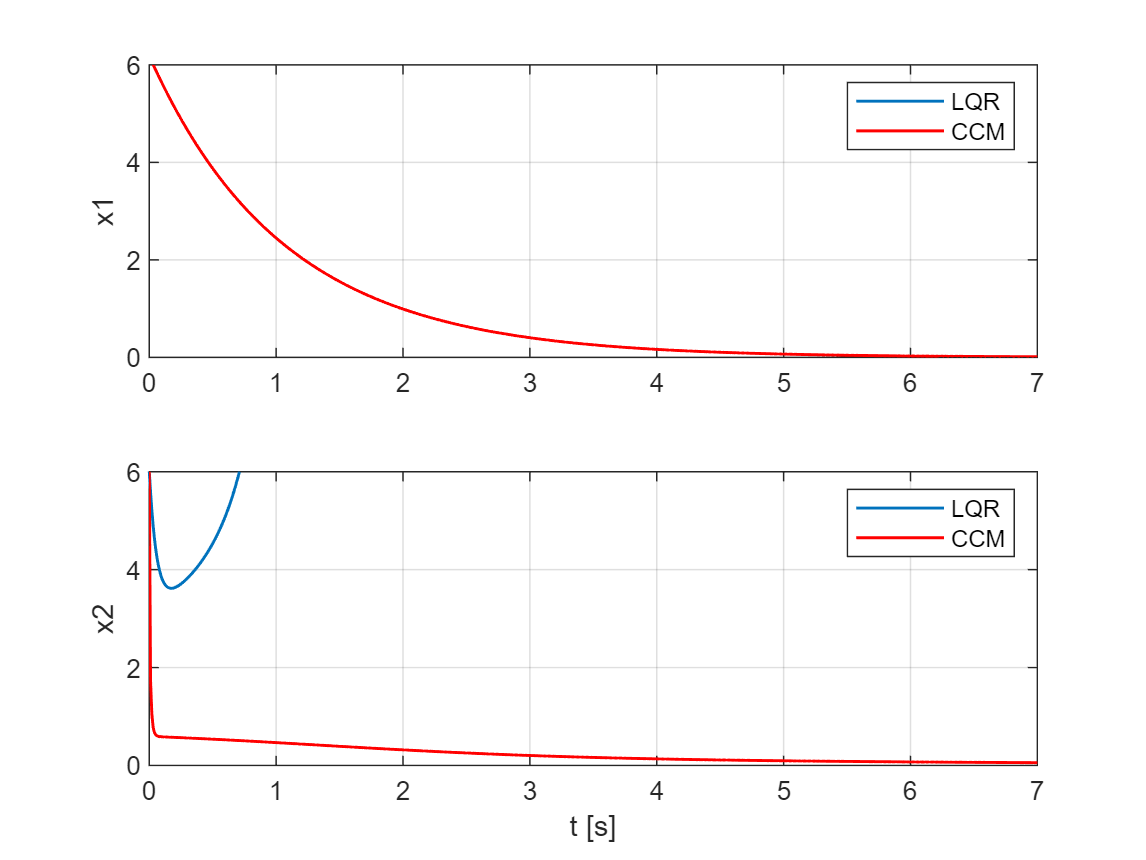

figure
subplot(nx,1,1)
plot(ts,xs_lqr(1,:),'LineWidth',1)
hold on
plot(ts,xs_ccm(1,:),'-r','LineWidth',1)
grid on
ylabel('x1')
ylim([0,6])
legend('LQR', 'CCM')
subplot(nx,1,2)
plot(ts,xs_lqr(2,:),'LineWidth',1)
hold on
plot(ts,xs_ccm(2,:),'-r','LineWidth',1)
grid on
ylabel('x2')
ylim([0,6])
legend('LQR', 'CCM')
xlabel('t [s]')

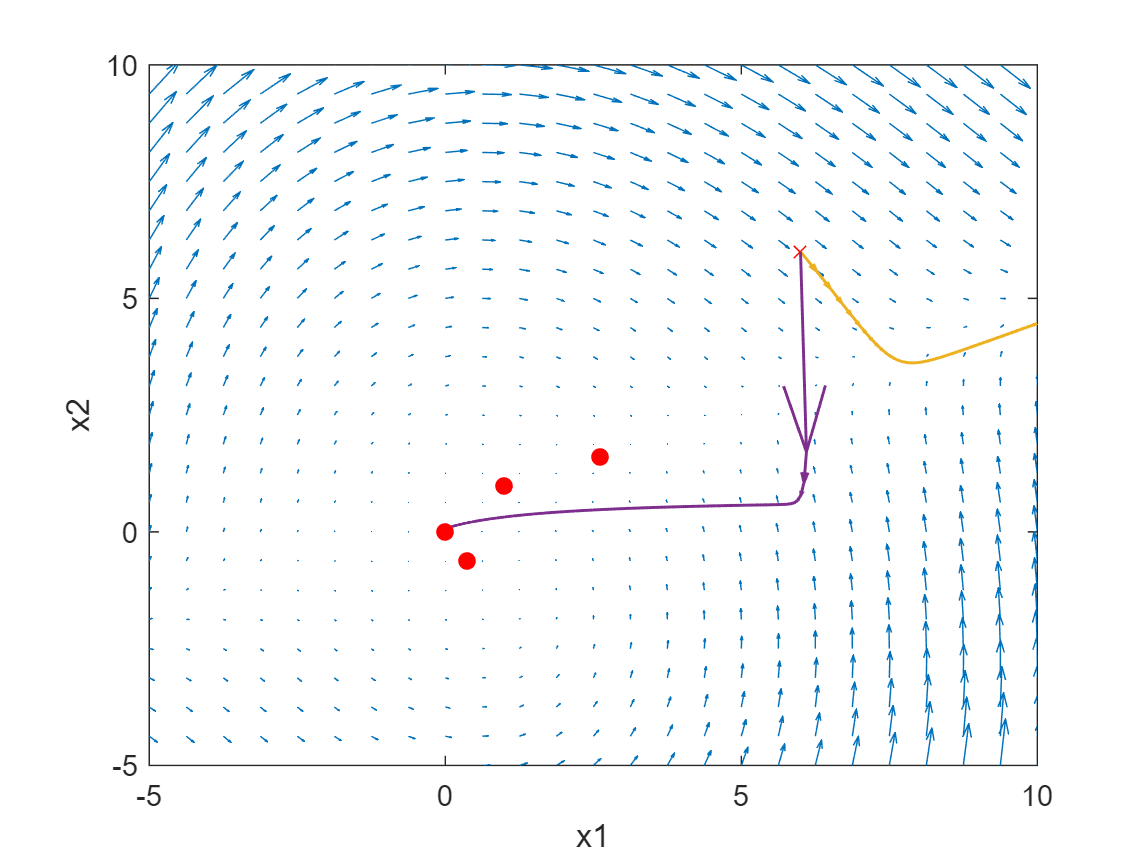

% Find equilibrium points
x_sym = sym('x',[nx,1],'real');
sols = solve(f(x_sym) == 0,x_sym);

% Visualize vector field
xis = linspace(-5,10,2.5e1);
[x1s,x2s] = meshgrid(xis, xis);
f1s = zeros(length(xis),length(xis));
f2s = zeros(length(xis),length(xis));
for i1=1:length(xis)
    for i2=1:length(xis)
        xi = [x1s(i1,i2);x2s(i1,i2)];
        xdi = f(xi);
        f1s(i1,i2) = xdi(1);
        f2s(i1,i2) = xdi(2);
    end
end

figure
% Plot vector field
quiver(x1s,x2s,f1s,f2s,'AutoScale','on','AutoScaleFactor',1.3)
hold on

% Plot controlled trajectories
scatter(x0(1),x0(2),'rx')

Narr = 1;  % adjust arrow spacing

plot(xs_lqr(1,:),xs_lqr(2,:),'LineWidth',1,'Color',[0.9290 0.6940 0.1250])
x1arr = xs_lqr(1,1:Narr:end-1);
x2arr = xs_lqr(2,1:Narr:end-1);
dx1arr = diff(xs_lqr(1,1:Narr:end));
dx2arr = diff(xs_lqr(2,1:Narr:end));
quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'filled', 'Color', [0.9290 0.6940 0.1250], ...
       'LineWidth', 1, 'MaxHeadSize', 5);

plot(xs_ccm(1,:),xs_ccm(2,:),'LineWidth',1,'Color',[0.4940 0.1840 0.5560])
x1arr = xs_ccm(1,1:Narr:end-1);
x2arr = xs_ccm(2,1:Narr:end-1);
dx1arr = diff(xs_ccm(1,1:Narr:end));
dx2arr = diff(xs_ccm(2,1:Narr:end));
quiver(x1arr, x2arr, dx1arr, dx2arr, 0, 'filled', 'Color', [0.4940 0.1840 0.5560], ...
       'LineWidth', 1, 'MaxHeadSize', 5);
% plot(xs_ccm(1,:),xs_ccm(2,:),'LineWidth',1,'Color',[0.4940 0.1840 0.5560])

% Plot Equilibrium points
scatter(sols.x1,sols.x2,'ro','filled')
axis tight
xlabel('x1')
ylabel('x2')
% xlim([-1.05,2.05])
% ylim([-1.05,2.05])
xlim([-5,10])
ylim([-5,10])